clear all;
N=500;
sigma=0;
P=4;
%generate some random signal
symbols=[1/sqrt(2)+j*1/sqrt(2),-1/sqrt(2)+j*1/sqrt(2),1/sqrt(2)-j*1/sqrt(2),-1/sqrt(2)-j*1/sqrt(2)];
indices=randi([1, 4], 1, N);

% for n =1:N
%     s(n)=symbols(indices(n));
% end

load("test_s.mat");
s=s.';
x=gendata_conv(s,P,N,sigma);

X=zeros(2*P,N-1);
for i =0:(N-2)
    X(:,i+1)=x(i*P+1:(i+2)*P);
end

% X=zeros(3*P,N-2);
% for i =0:(N-3)
%     X(:,i+1)=x(i*P+1:(i+3)*P);
% end

rank(X)

ans = 2

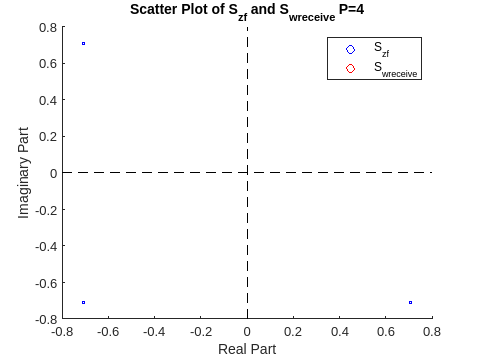

sigma=0.0;
x=gendata_conv(s,P,N,sigma);

X=zeros(2*P,N-1);
for i =0:(N-2)
    X(:,i+1)=x(i*P+1:(i+2)*P);
end

h=zeros(1,P);
for i=1:P
    b=(i-1)/P;
    if b>=0 && b<0.25 || b>=0.5 && b<0.75
        h(i)=1;
    elseif b>=0.25 && b<0.5 || b>=0.75 && b<1
        h(i)=-1;
    end
end

%lets construct H and S in matrix form
H=[zeros(P,1),h';h',zeros(P,1)];
S=[s(2:end);s(1:end-1)];

% Build wiener receiver
W_wiener=(inv(H*H'+sigma^2*eye(2*P))*H)';
S_est_wreceive=W_wiener*X;

%build zero forcing
W_zf=pinv(H);
S_est_zf=W_zf*X;

scatter(real(S_est_zf(1,:)), imag(S_est_zf(1,:)), 'b', 'SizeData', 5);
hold on;
scatter(real(S_est_wreceive(:)), imag(S_est_wreceive(:)), 'r', 'SizeData', 5);
xlim = get(gca,'Xlim');
ylim = get(gca,'Ylim');
plot(xlim,[0,0],'k--');
plot([0,0],ylim,'k--');
hold off;
xlabel('Real Part');
ylabel('Imaginary Part');
title('Scatter Plot of S_{zf} and S_{wreceive} P=4');
legend('S_{zf}', 'S_{wreceive}');

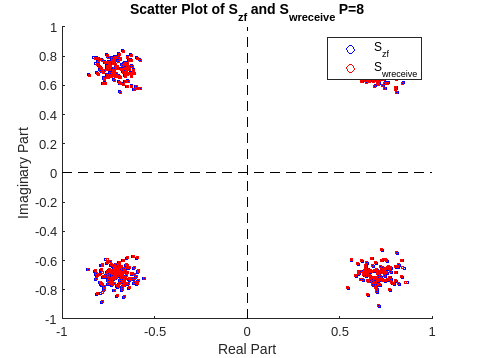

N=500;
P_2=8;
x=gendata_conv(s,P_2,N,sigma);
X=zeros(2*P_2,N-1);
for i =0:(N-2)
    X(:,i+1)=x(i*P_2+1:(i+2)*P_2);
end

h=zeros(1,P_2);
for i=1:P_2
    b=(i-1)/P_2;
    if b>=0 && b<0.25 || b>=0.5 && b<0.75
        h(i)=1;
    elseif b>=0.25 && b<0.5 || b>=0.75 && b<1
        h(i)=-1;
    end
end

%lets construct H and S in matrix form
H=[zeros(P_2,1),h';h',zeros(P_2,1)];
S=[s(2:end);s(1:end-1)];

% Build wiener receiver
W_wiener=(inv(H*H'+sigma^2*eye(2*P_2))*H)';
S_est_wreceive=W_wiener*X;

%build zero forcing
W_zf=pinv(H);
S_est_zf=W_zf*X;


scatter(real(S_est_zf(:)), imag(S_est_zf(:)), 'b', 'SizeData', 5);
hold on;
scatter(real(S_est_wreceive(:)), imag(S_est_wreceive(:)), 'r', 'SizeData', 5);
xlim = get(gca,'Xlim');
ylim = get(gca,'Ylim');
plot(xlim,[0,0],'k--');
plot([0,0],ylim,'k--');
hold off;
xlabel('Real Part');
ylabel('Imaginary Part');
title('Scatter Plot of S_{zf} and S_{wreceive} P=8');
legend('S_{zf}', 'S_{wreceive}');

Functions

function x = gendata_conv(s,P,N,sigma)
real_noise = randn(1, N*P);
imag_noise = randn(1, N*P);
complex_noise = (real_noise + 1i * imag_noise) / sqrt(2);
x=zeros(1,N*P);
    for j = 1:N*P
        for k=1:N
            t=(j-1)/P-(k-1);
            h=0;
            if t>=0 && t<0.25 || t>=0.5 && t<0.75
                h=1;
                x(j)=x(j)+h*s(k);
            elseif t>=0.25 && t<0.5 || t>=0.75 && t<1
                h=-1;
                x(j)=x(j)+h*s(k);
            end
            
        end
        x(j)=x(j)+sigma*complex_noise(j);
    end
end


